# Classification of Differential Equations 

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

When modeling many real-world applications, the quantity of a variable is often related to the rate of change (or derivative) of that variable. Any equation that has terms with derivatives is known as a **differential equation**.

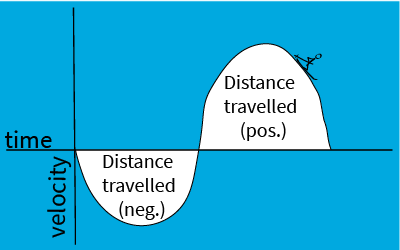

Before we can start solving various real-world examples of differential equations, we first need to learn how to classify them, so we can identify the correct analytical methods to use.

**Before you get started**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2 hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Classification of Differential Equations

### Independent and Dependent Variables

In differential equations, we take the derivative of dependent variables with respect to independent variables.

Consider the following equation:


$$\frac{d^2y}{dt^2} + 2 \frac{dy}{dt} + (y-1) = 3t$$


$\frac{dy}{dt}$ means we are differentiating $y$ with respect to $t$. This means that $y$ is the dependent variable, and $t$ is the independent variable. $\frac{d^2y}{dt^2}$ represents the second derivative of $y$ with respect to $t$.

It is common for $t$ (representing time) to be the independent variable when modeling real-world applications.

 **Notes on Notation:  **Differential equations typically use the simpler notation of $y'$ and $y''$, etc, in equations where the independent variable is clearly understood. The above equation can be rewritten as follows.

 
$$y'' + 2 y' + (y-1) = 3t$$


Another common shorthand is $\dot{y}$ and $\ddot{y}$, which specifically refer to derivatives with respect to time.

### ODEs and PDEs

Equations with one ***independent*** variable are known as ***ordinary*** differential equations (ODEs).


$$\frac{d^2y}{dx^2} + 2 \frac{dy}{dx} = x^2$$


In this equation, $x$ is the only independent variable, while $y=y(x)$ is a dependent variable, so this is an ODE.

Equations with multiple ***independent*** variables are known as ***partial ***differential equations (PDEs).

 
$$2 \frac{\partial u}{\partial x} - \frac{\partial u}{\partial y}  = 3xy

$$


In this equation, both $x$ and $y$ are independent variables, while $u = u(x,y)$ is a dependent variable, so this is a PDE. 

Note that partial derivatives are denoted by a different symbol, $\partial$.

### Check Your Understanding

**Exercise 1.** Consider the following differential equation:  


$$2 \frac{\partial a}{\partial b} + \frac{\partial a}{\partial c}  = 0$$


 a. Select the independent variable(s) in this differential equation.

CheckExercise1a(false,true,true);
 

 b. Is this an ordinary or partial differential equation?

type1 = "a PDE";
CheckExercise1b(type1);
 

**Exercise 2.** Consider the following differential equation.


$$3 \frac{da}{db} + a  = bc$$


 a. Select the independent variable(s) in this differential equation.

CheckExercise2a(false,true,false);
 

 b. Is this an ordinary or partial differential equation?

type2 = "an ODE";
CheckExercise2b(type2);
 

  Note that the rest of this courseware module will only focus on ordinary differential equations. Partial differential equations are covered by the [Applied Partial Differential Equations](https://www.mathworks.com/matlabcentral/fileexchange/172650-applied-partial-differential-equations) course.

## Classification of Ordinary Differential Equations

The solution methods for ordinary differential equation depend on three parameters: order, linearity, and homogeneity.

### Order

The order of a differential equation represents the highest derivative that appears in the equation. In general, the lower the order, the easier it will be to solve the ODE. 

For example, $y' + y = 3t$ is a first-order differential equation, and $y'' + 2y' + y = 0$ is a second-order differential equation.

The order of a differential equation is important in determining the analytical methods that can be used to solve the equation. For example,

- When solving first-order differential equations, you can use [separation of variables](matlab:open('./SeparationOfVariablesSoln.mlx')) or [integrating factors](matlab:open('./IntegratingFactorsSoln.mlx')).

- When solving second-order differential equations, you can use [characteristic equations](matlab:open('./CharacteristicEquationsSoln.mlx')) or [undetermined coefficients](matlab:open('./UndeterminedCoefficientsSoln.mlx')).

### Linearity

A differential equation is linear if it can be written in the following form.


$$f_1(t)\cdot y^{(n)} + f_2(t)\cdot y^{(n - 1)} + ... + f_n(t)\cdot y = g(t)$$


The coefficients of the dependent variable, $y$, and all of its derivatives, are either constant, or functions of the independent variable.

For example,

- $3 y'' + 2t \cdot y' + 4y = 10t$ is a linear ODE

- $y'' + 4y' \cdot y = 0$ and $y'' + y' = y^2$ are nonlinear ODEs

In order to better explain the concept of linearity, consider the **Principle of Superposition: **If $y_1$ and $y_2$ are both solutions to a homogeneous linear differential equation, $L(y) = 0$, then any linear combination $c_1 \cdot y_1 + c_2 \cdot y_2$ is ***also*** a solution to the equation.

The linearity of ordinary differential equations is important, because many of the most common analytical methods to solve ODEs, like [integrating factors](matlab:open('./IntegratingFactorsSoln.mlx')), [characteristic equations](matlab:open('./CharacteristicEquationsSoln.mlx')), and [undetermined coefficients](matlab:open('./UndeterminedCoefficientsSoln.mlx')), can only be used for linear equations.

### Homogeneity

To solve a linear ordinary differential equation analytically, we need to determine its homogeneity.


$$f_1(t)\cdot y^{(n)} + f_2(t)\cdot y^{(n - 1)} + ... + f_n(t)\cdot y = g(t)$$


- If $g(t) = 0$, then the equation is ***homogeneous.***

- If $g(t) \neq 0$, then the equation is ***nonhomogeneous.***

In other words, a linear ODE is homogeneous if the trivial solution $y = 0$ is a solution.

The homogeneity of a differential equation is important in determining the analytical methods that can be used to solve the equation. In general, it is typically easier to solve homogeneous ODEs.

For example, [the method of undetermined coefficients](matlab:open('./UndeterminedCoefficientsSoln.mlx')) is an analytical method that is specifically used to solve nonhomogeneous ODEs.

### Check Your Understanding

**Exercise 3.**

Consider the following differential equation:


$$y'''' +4t \cdot y'' + y = 2t^2$$


 a. What is the order of this equation?

CheckOrder3(4);
 

 b. Is this equation linear or nonlinear?

CheckLinearity3("linear");
 

 c. If linear, is this equation homogeneous or nonhomogeneous? 

CheckHomogeneity3("nonhomogeneous");
 

**Exercise 4.**

Consider the following differential equation.


$$y''' + y' \cdot y = 0$$


 a. What is the order of this equation?

CheckOrder4(3);
 

 b. Is this equation linear or nonlinear?

CheckLinearity4("nonlinear");
 

 c. If linear, is this equation homogeneous or nonhomogeneous? 

CheckHomogeneity4("N/A - not linear");
 

**Exercise 5.**

Consider the following differential equation:


$$y'' + 2y' = 3y$$


 a. What is the order of this equation?

CheckOrder5(2);
 

 b. Is this equation linear or nonlinear?

CheckLinearity5("linear");
 

 c. If linear, is this equation homogeneous or nonhomogeneous? 

CheckHomogeneity5("homogeneous");
 

## Solving Differential Equations

Finally, in this course, we are going to be exploring different methods for solving ordinary differential equations analytically. But before examining these methods, what does it actually mean to "solve" a differential equation? What does this solution look like?

### Analytical Solutions

In a differential equation where $x$ is the independent variable and $y$ is the dependent variable, an analytical solution is an expression for $y$ in terms of $x$, without any derivative terms. For example, given the following differential equation:


$$\frac{dy}{dx} = x \cdot y$$


The analytical solution looks like this:


$$y = Ce^{\frac{x^2}{2}}$$


You may notice that $y$ is also dependent on a constant $C$. This is because if we don't have initial data for the differential equation, then there is an infinite family of possible solutions parameterized by $C$. 

- A solution that contains an arbitrary constant $C$ is known as a **general solution**, and encompasses all possible solutions to the ODE.

- On the other hand, a **particular solution** is a solution that does not include any arbitrary constants, such as the solution we obtain if we have an initial condition to satisfy. 

Now, in addition to the differential equation, let's say that we have an initial condition $y(0) = 2$. Then we can find the particular solution.


$$2 = Ce^{\frac{0^2}{2}}$$
     
$$2 = Ce^{0}$$
     
$$2 = C$$
 


$$y = 2e^{\frac{1}{2}x^2}$$


### Qualitative Solutions

Graphically, solutions to first-order differential equations are represented by a slope field.

PlotSlopeField(false);

In this example, where $y$ is the dependent variable and $x$ is the independent variable, the slopes of the arrows show us the derivative $\frac{dy}{dx}$ at every point $(x, y)$. This illustrates why the **general solution** encompasses an infinite number of possible solutions.

PlotSlopeFieldWithLines(false);

Each **particular solution** is represented by the curve that is uniquely identified by a point that corresponds to an initial condition, $(x_0,y_0)$, that the solution must pass through.

If you'd like to learn more about qualitative analysis, be sure to check out the [Qualitative Analysis of ODEs](https://www.mathworks.com/matlabcentral/fileexchange/95513-qualitative-analysis-of-odes) courseware and the [Phase Plane and Slope Field apps](https://www.mathworks.com/matlabcentral/fileexchange/91705-phase-plane-and-slope-field-apps).

### Numerical Solutions

Instead of finding an exact expression for $y$ in terms of $x$, numerical methods are also commonly used to find an approximation for the value of $y$ at different points. This is useful in cases where differential equations cannot be solved analytically.

  This course will just focus on analytical methods, but if you'd like to learn more in-depth about these numerical methods, check out the [Numerical Methods with Applications](https://www.mathworks.com/matlabcentral/fileexchange/111490-numerical-methods-with-applications) course.

  MATLAB has built-in functionality that makes it easy to solve differential equations numerically, and visualize your results.

ShowCodeAndGraph(false);

  You can learn about this in the self-paced online course [Solving Ordinary Differential Equations with MATLAB](https://matlabacademy.mathworks.com/details/solving-ordinary-differential-equations-with-matlab/odes).

Given that numerical methods do a great job of approximating differential equations, and can be easily computed by software tools like MATLAB, you may ask- what is the point of learning analytical methods?

While it is true that numerical methods may be the best tool in some circumstances, the exact expressions that analytical solutions provide are very valuable for gaining a deeper insight into the behavior of a solution, and allow for a clearer understanding of how changes in parameters can impact the solution.

[⇦ Return to the main menu](matlab:open('MainMenu.mlx'))

## Local Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

% exercise 1
function CheckExercise1a(aSelected, bSelected, cSelected)
    if ~aSelected && ~bSelected && ~cSelected
        disp("Please select one or more variables.")
    elseif ~aSelected && bSelected && cSelected
        disp("Correct! b and c are the independent variables in this equation.")
    elseif ~aSelected
        disp("Incorrect- remember that some differential equations may have multiple independent variables.")
    else
        disp("Incorrect- remember that independent variables are the variables we are differentiating with respect to.")
    end
end

function CheckExercise1b(type1)
    if type1 == ""
        disp("Please select an answer.")
    elseif type1 == "a PDE"
        disp("Correct! This is a partial differential equation, because it has more than one independent variable.")
    else
        disp("Incorrect- remember that an ordinary differential equation has only one independent variable.")
    end
end


% exercise 2
function CheckExercise2a(aSelected, bSelected, cSelected)
    if ~aSelected && ~bSelected && ~cSelected
        disp("Please select one or more variables.")
    elseif ~aSelected && bSelected && ~cSelected
        disp("Correct! b is the only independent variable in this equation.")
    elseif ~aSelected && bSelected && cSelected
        disp("Incorrect- for this equation, let's assume that c is a constant. But there are scenarios where that is not a good assumption.")
    else
        disp("Incorrect- remember that independent variables are the variables we are differentiating with respect to.")
    end
end

function CheckExercise2b(type2)
    if type2 == ""
        disp("Please select an answer.")
    elseif type2 == "an ODE"
        disp("Correct! This is an ordinary differential equation, because it has one independent variable.")
    else
        disp("Incorrect- remember that partial differential equations have more than one independent variable.")
    end
end

% order exercises
function CheckOrder3(answer)
    CheckOrder(answer, 4)
end

function CheckOrder4(answer)
    CheckOrder(answer, 3)
end

function CheckOrder5(answer)
    CheckOrder(answer, 2)
end

function CheckOrder(answer, correct_order)
    if answer == 0
        disp("Please enter a nonzero order.")
    elseif answer == correct_order
        disp("Correct! The " + NumToRank(correct_order) + " derivative of y is the highest derivative that appears in the equation, so the order is " + correct_order + ".")
    else
        disp("Incorrect- remember that the order of a differential equation is the highest derivative that appears in the equation.")
    end
end

function rank = NumToRank(num)
    switch num
        case 2
            rank = "second";
        case 3
            rank = "third";
        case 4
            rank = "fourth";
    end
end

% linearity exercises
function CheckLinearity3(answer)
    CheckLinearity(answer, "linear")
end

function CheckLinearity4(answer)
    CheckLinearity(answer, "nonlinear", "y' * y")
end

function CheckLinearity5(answer)
    CheckLinearity(answer, "linear")
end

function CheckLinearity(answer, correct, nonlinear_term)
    if answer == ""
        disp("Please select an answer.")
    elseif answer ~= correct
        disp("Incorrect- check again to see if this equation fits the form of a linear differential equation.")
    elseif answer == "linear"
        disp("Correct! All coefficients of y and its derivatatives are constant or functions of t, so the equation is linear.")
    else
        disp("Correct! The equation has a nonlinear term " + nonlinear_term + ", so the equation is nonlinear.")
    end
end



% homogeneity exercises
function CheckHomogeneity3(answer)
    if answer == ""
        disp("Please select an answer.")
    elseif answer == "nonhomogeneous"
        disp("Correct! The trivial solution y=0 is not a solution, so the equation is nonhomogeneous.")
    elseif answer == "N/A - not linear"
        disp("Incorrect- we saw in part (b) that this is a linear equation.")
    else
        disp("Incorrect- remember that in homogeneous equations, the trivial solution y=0 is always a solution.")
    end
end

function CheckHomogeneity4(answer)
    if answer == ""
        disp("Please select an answer.")
    elseif answer == "N/A - not linear"
        disp("Correct! Because the equation is nonlinear, we can't assess its homogeneity.")
    else
        disp("Incorrect- we saw in part (b) that this is a nonlinear equation, so we can't assess its homogeneity.")
    end
end

function CheckHomogeneity5(answer)
    if answer == ""
        disp("Please select an answer.")
    elseif answer == "homogeneous"
        disp("Correct! The trivial solution y=0 is a solution, so the equation is homogeneous.")
    elseif answer == "N/A - not linear"
        disp("Incorrect- we saw in part (b) that this is a linear equation.")
    else
        disp("Incorrect- remember that in nonhomogeneous equations, the trivial solution y=0 is not a solution.")
    end
end

function ShowCodeAndGraph(checked)
    if checked
        F = ode;
        F.ODEFcn = @(x, y) x * y;
        F.InitialValue = 1;
        solution = solve(F, -2, 2);
        
        disp("F = ode;")
        disp("F.ODEFcn = @(x, y) x * y;")
        disp("F.InitialValue = 1;")
        disp("solution = solve(F, -2, 2);")
        disp("plot(solution.Time, solution.Solution)")
        
        plot(solution.Time, solution.Solution)
    end
end

function PlotSlopeField(checked)
    if checked
        % Define the range for x and y
        xRange = -5:0.5:5;
        yRange = -5:0.5:5;
        
        % Create a grid of x and y values
        [X, Y] = meshgrid(xRange, yRange);
        
        % Define the differential equation dy/dx = x + y
        dYdX = X + Y;
        
        % Normalize the vectors for uniform arrow length
        L = sqrt(1 + dYdX.^2);
        U = 1 ./ L; % dx component (always 1 for slope representation)
        V = dYdX ./ L; % dy component
        
        % Plot the slope field using quiver
        figure;
        quiver(X, Y, U, V, 'AutoScale', 'on');
        xlabel('x');
        ylabel('y');
        title('Slope Field for dy/dx = x + y');
        axis tight;
        grid on;
    end
end

function PlotSlopeFieldWithLines(checked)
    if checked
        % Define the range for x and y
        xRange = -5:0.5:5;
        yRange = -5:0.5:5;
        
        % Create a grid of x and y values
        [X, Y] = meshgrid(xRange, yRange);
        
        % Define the differential equation dy/dx = x + y
        dYdX = X + Y;
        
        % Normalize the vectors for uniform arrow length
        L = sqrt(1 + dYdX.^2);
        U = 1 ./ L; % dx component (always 1 for slope representation)
        V = dYdX ./ L; % dy component
        
        % Plot the slope field using quiver
        figure;
        quiver(X, Y, U, V, 'AutoScale', 'on');
        xlabel('x');
        ylabel('y');
        title('Slope Field for dy/dx = x + y');
        axis([-5 5 -5 5]);
        grid on;
        hold on;

        syms x;
        y1 = -x - 1;
        y2 = exp(x) - x - 1;
        y3 = 3 * exp(x) - x - 1;
        y4 = -2 * exp(x) - x - 1;
        y5 = -20 * exp(x) - x - 1;
        fplot(y1, [-5 5], 'LineWidth', 1.5);
        hold on;
        fplot(y2, [-5 5], 'LineWidth', 1.5);
        hold on;
        fplot(y3, [-5 5], 'LineWidth', 1.5);
        hold on;
        fplot(y4, [-5 5], 'LineWidth', 1.5);
        hold on;
        fplot(y5, [-5 5], 'LineWidth', 1.5);
        hold off;
    end
end